%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%
% Compare_TIWE_EQ14_dist
%
% Compare distributions of N2, chi etc. from EQ14 to some TIWE data to see
% if they are similar. If they are very different, maybe we are computing
% them wrong in EQ14?
%
%
% 10/19/16 - A.Pickering
%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

clear ; close all

load('/Users/Andy/Cruises_Research/ChiPod/TIWE/events_TIWE.mat')

dir_base='/Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/Data/chameleon/processed';
clear cham
load( fullfile( dir_base, '/Cstar=0_01366/sum/eq14_sum.mat') )

% only use values above epsilon cnoise floor
%ig=find(log10(A.eps)>-8);

% get variables
%n2=A.N2(ig);
%dtdz=A.tgrad(ig);
%chi=A.chi(ig);
%eps=A.eps(ig);

% EQ14 data just from patches I identified
load('/Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/mfiles/Patches/eq14_INpatch.mat')


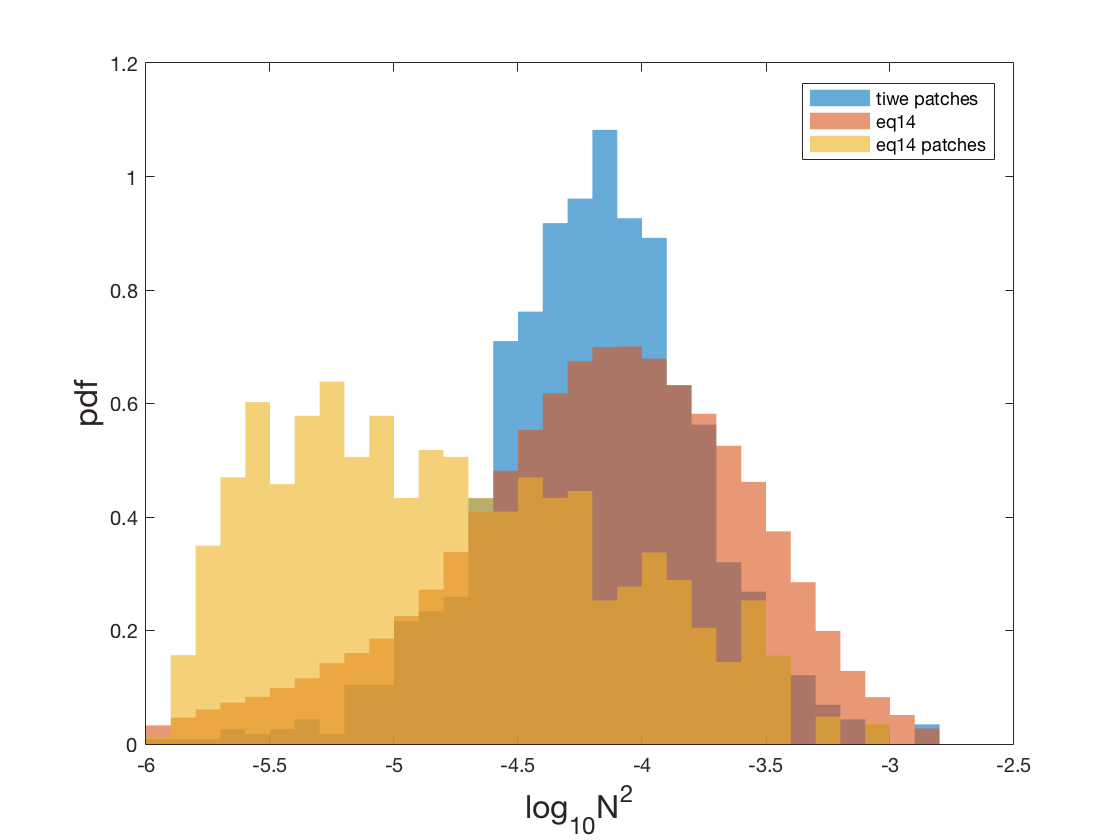

figure(1);clf
h1=histogram(log10(A.N2(:)),'Normalization','pdf','edgecolor','none');
hold on
h2=histogram(real(log10(cham.N2(:))),h1.BinEdges,'Normalization','pdf','edgecolor','none');
h3=histogram(real(log10(n2_patches(:))),h1.BinEdges,'Normalization','pdf','edgecolor','none');
legend([h1 h2 h3],'tiwe patches','eq14','eq14 patches')
xlabel('log_{10}N^2','fontsize',16)
ylabel('pdf','fontsize',16)

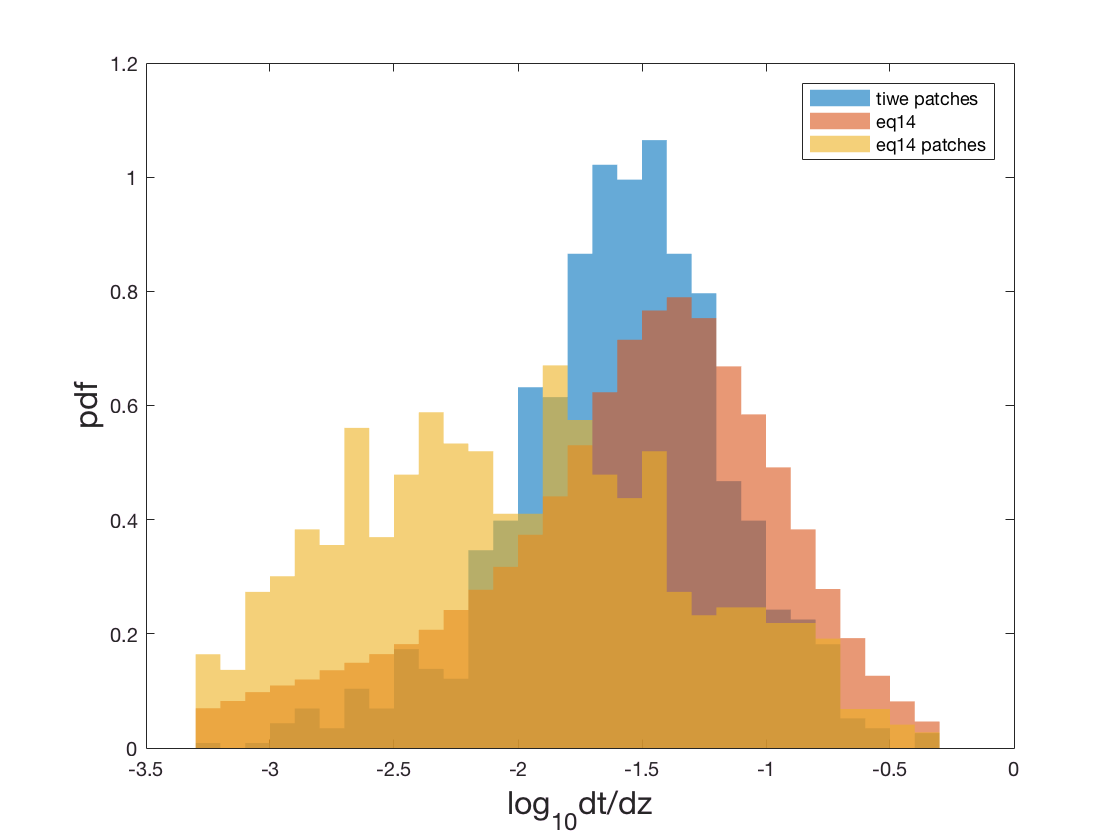


figure(2);clf
h1=histogram(real(log10(A.tgrad(:))),'Normalization','pdf','edgecolor','none');
hold on
h2=histogram(real(log10(cham.DTDZ_RHOORDER(:))),h1.BinEdges,'Normalization','pdf','edgecolor','none');
h3=histogram(real(log10(dtdz_patches(:))),h1.BinEdges,'Normalization','pdf','edgecolor','none');
legend([h1 h2 h3],'tiwe patches','eq14','eq14 patches')
xlabel('log_{10}dt/dz','fontsize',16)
ylabel('pdf','fontsize',16)

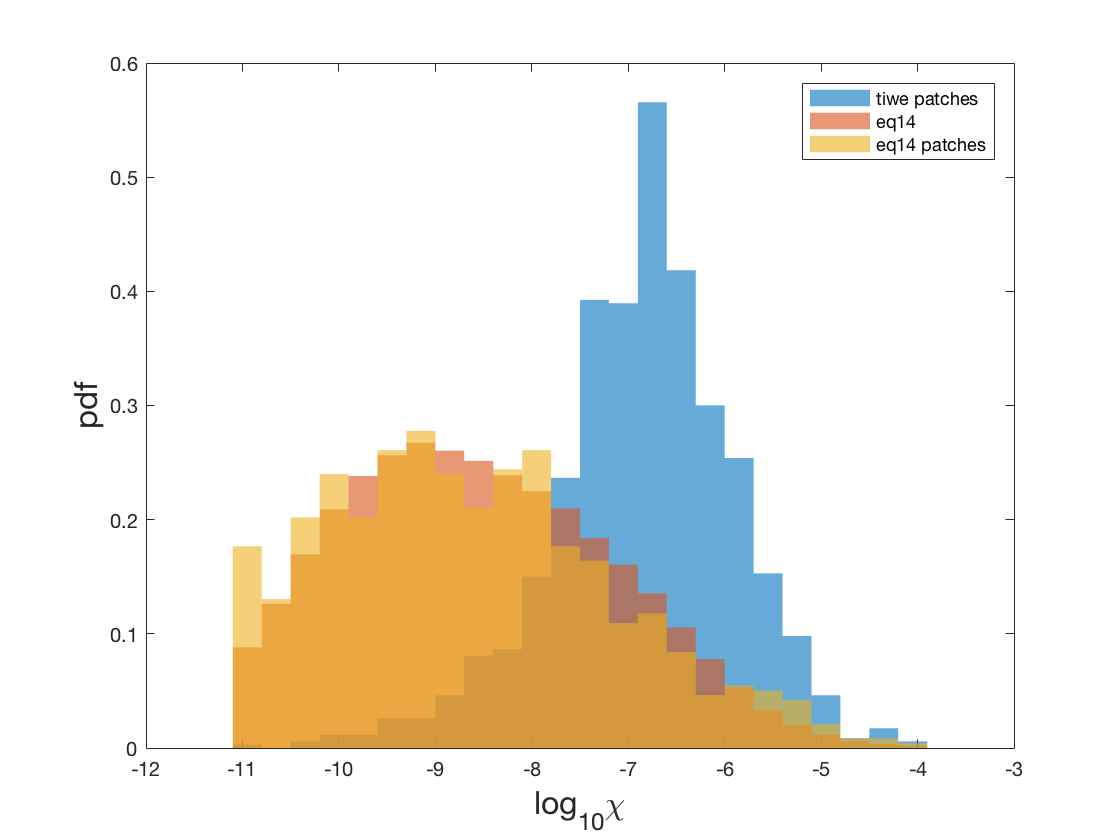


figure(3);clf
h1=histogram(log10(A.chi(:)),'Normalization','pdf','edgecolor','none');
hold on
h2=histogram(real(log10(cham.CHI(:))),h1.BinEdges,'Normalization','pdf','edgecolor','none');
h3=histogram(real(log10(chi_patches(:))),h1.BinEdges,'Normalization','pdf','edgecolor','none');
legend([h1 h2 h3],'tiwe patches','eq14','eq14 patches')
xlabel('log_{10}\chi','fontsize',16)
ylabel('pdf','fontsize',16)

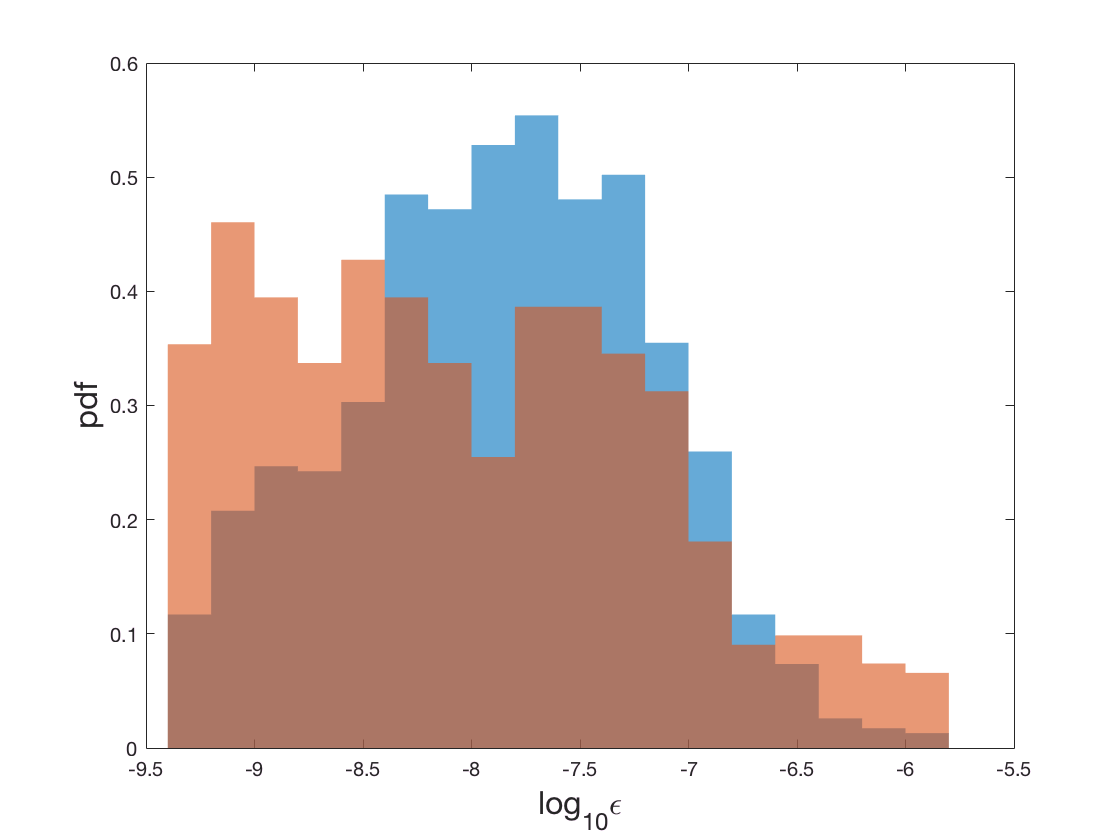


figure(4);clf
h1=histogram(log10(A.eps(:)),'Normalization','pdf','edgecolor','none');
hold on
h2=histogram(real(log10(cham.EPSILON(:))),h1.BinEdges,'Normalization','pdf','edgecolor','none');
h3=histogram(real(log10(eps_patches(:))),h1.BinEdges,'Normalization','pdf','edgecolor','none');
legend([h1 h2 h3],'tiwe patches','eq14','eq14 patches')
xlabel('log_{10}\epsilon','fontsize',16)
ylabel('pdf','fontsize',16)